# **Modélisation mathématiques du dirigeable**

clc; clear;

## Données :

g = 9.80665;
rho = 1.225;
diameter = 12.7*10^(-2);
radius = diameter/2;

key = ["gravity", "rho", "diameter"];
value = [g, rho, diameter];
data = containers.Map(key, value);

% Avec DataSheet
estimated_RPM = [18638.0, 21387.0, 24030.0, 25845.0, 27685.0, 29601.0];
voltage = [11.20, 17.5, 23.04, 28.52, 35.37, 40.01];
thrust = [652.9, 885.6, 1127.5, 1382.4, 1634.9, 1814.4] * g * 10^(-3);

% Clés et valeurs pour la map
keys_m = {'estimated_RPM', 'voltage', 'thrust'};
values_m = {estimated_RPM, voltage, thrust};

% Création de la map
data_m = containers.Map(keys_m, values_m);

% Axes du dirigeable
x_m = [1; 0; 0];
y_m = [0; 1; 0];
z_m = [0; 0; 1];

key_axes_m = {'x_m', 'y_m', 'z_m'};
value_axes_m = {x_m, y_m, z_m};
data_axes = containers.Map(key_axes_m, value_axes_m);

% angle du servomoteur
angle = pi/4;

## Classe moteur :

Prop = Moteur(data, data_m, data_axes, angle)

Prop =   Moteur with properties:

      Data: [3×1 containers.Map]
    Data_m: [3×1 containers.Map]
    Axes_m: [3×1 containers.Map]
     Angle: 0.7854



disp("Données d'interpolation :")

Données d'interpolation :


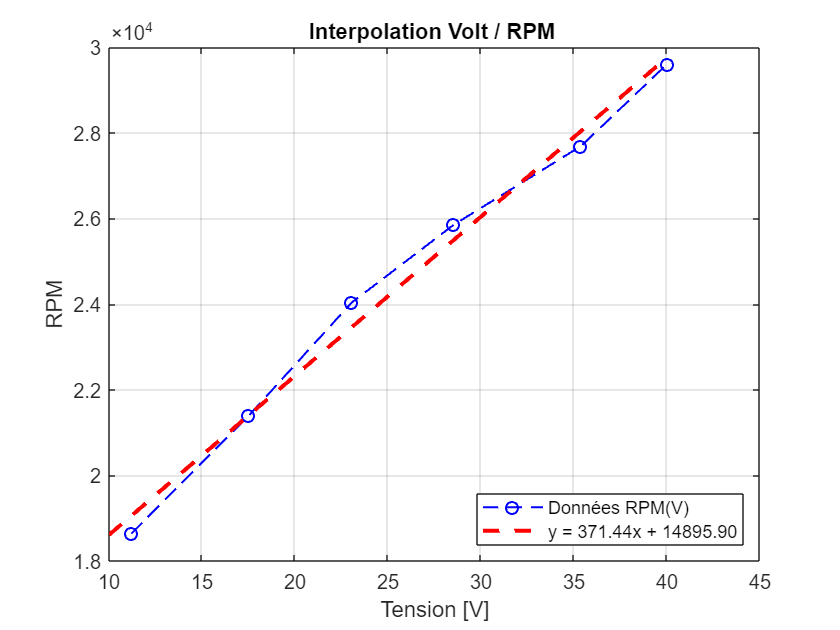

a = 371.4380

b = 1.4896e+04

[a, b] = Prop.interp_rpm_v()

mean_ct = Prop.average_C_t()

mean_ct = 0.2223

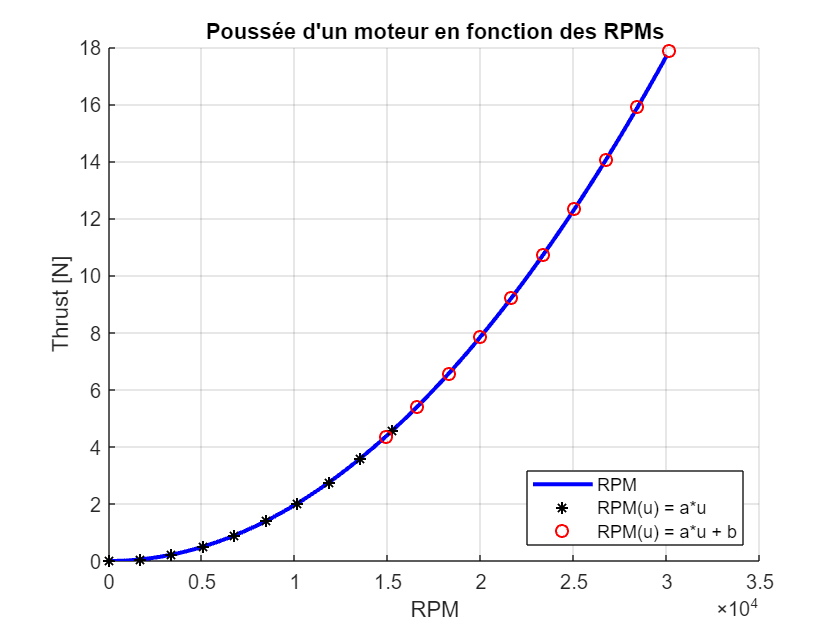

Prop.interp_thrust(a, b)

On trouve donc deux "domaines" pour exprimer $\mathrm{RPM}=f\left(U\right)$:


$$\left\lbrace \begin{array}{ll}
{\mathrm{RPM}}_1 =371\ldotp 4380\times U & ,0-50%\;\mathrm{de}\;\mathrm{la}\;\mathrm{puissance}\\
{\mathrm{RPM}}_2 =371\ldotp 4380\times U+14896 & ,50-100%\;\mathrm{de}\;\mathrm{la}\;\mathrm{puissance}
\end{array}\right.$$


power = 60

power = 60

u = 40;

keys_prop = ["Ct", "puissance", "a", "b", "voltage"];
value_prop = [mean_ct, power, a, b, u];

value_interp = containers.Map(keys_prop, value_prop)

value_interp =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: double



[F_prop, M_prop] = Prop.Force_Moment(value_interp)

F_prop =    12.3200
         0
   12.3200


M_prop =      0
     0
     0
